# Wavelet Transform to remove noise

### understanding our signals

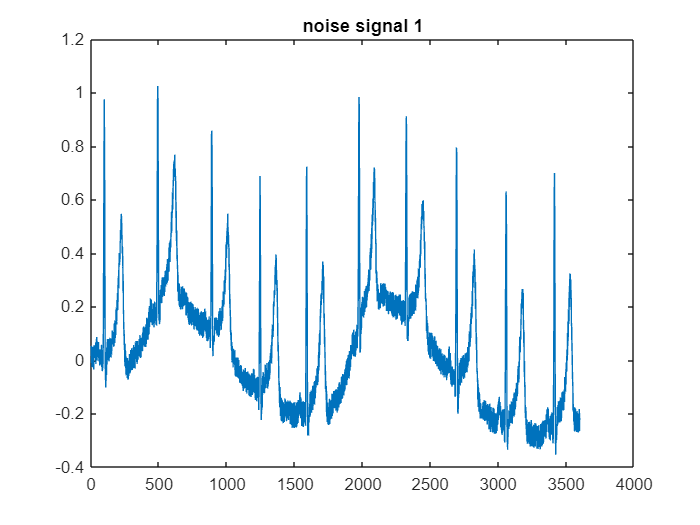

plot(ecg_rang_signal)
title('noise signal 1')

### Decomposing the wave

wname = 'sym6';
no_of_decompositions = 5;
[c,l] = wavedec(ecg_rang_signal,no_of_decompositions,wname);

### Plotting all the decomposed waves

decomposed_waves = detcoef(c,l,N);

where N is the nth level decomposition

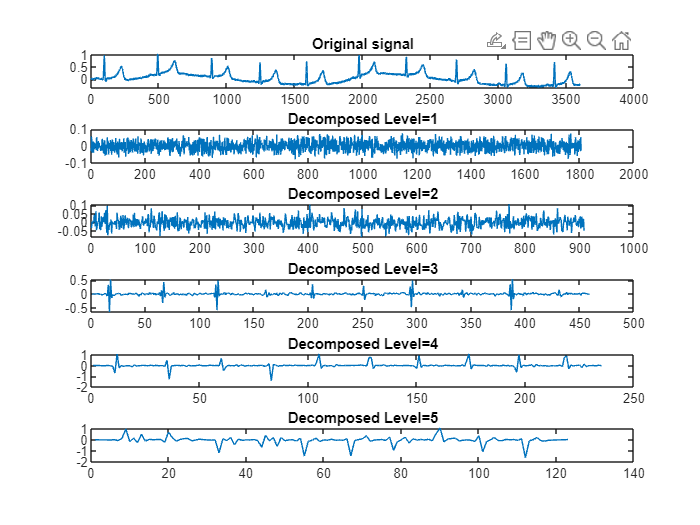

clf
subplot(6,1,1)
plot(ecg_rang_signal)
title('Original signal')

for i=1:5
    decomposed_wave = detcoef(c,l,i);
    subplot(6,1,i+1)
    plot(decomposed_wave)
    title(['Decomposed Level=',num2str(i)])
end

### Thresholding

by keeping a threshold to retail peak values or sudden changes we remove small values. 

thresholded_signal = wden(ecg_rang_signal,'rigrsure','s','sln',no_of_decompositions,wname)

thresholded_signal =     0.0226    0.0224    0.0221    0.0220    0.0218    0.0216    0.0214    0.0213    0.0211    0.0211    0.0210    0.0211    0.0211    0.0211    0.0211    0.0212    0.0213    0.0214    0.0216    0.0219    0.0224    0.0231    0.0241    0.0252    0.0264    0.0278    0.0293    0.0307    0.0320    0.0329    0.0335    0.0343    0.0347    0.0345    0.0340    0.0331    0.0329    0.0351    0.0385    0.0424    0.0455    0.0451    0.0428    0.0398    0.0371    0.0368    0.0377    0.0387    0.0398    0.0404


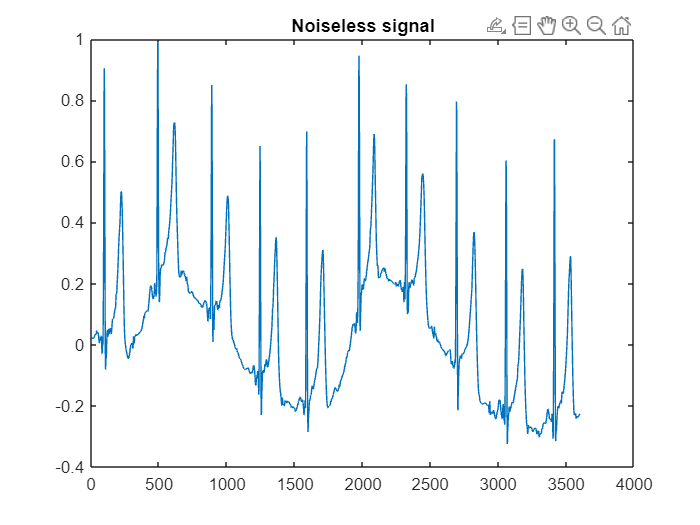

clf
plot(thresholded_signal)

title('Noiseless signal')

### Comparision

compairing the noisy signal and signal after wavelet analysis.

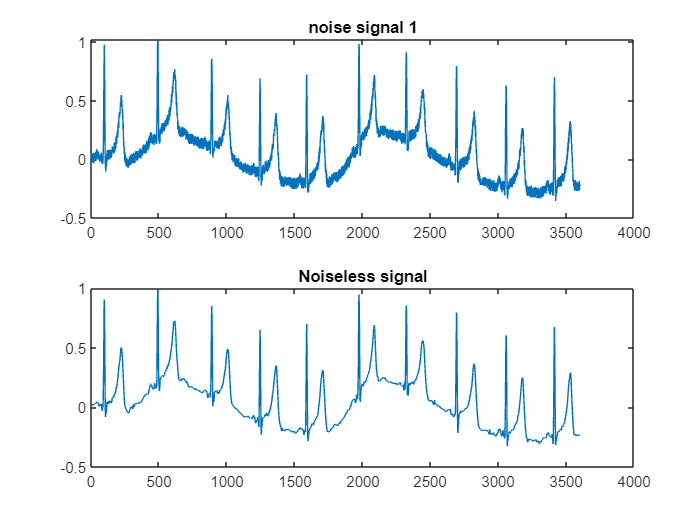

clf
subplot(2,1,1)
plot(ecg_rang_signal)
title('noise signal 1')

subplot(2,1,2)
plot(thresholded_signal)
title('Noiseless signal')